## Ejercicio 2 (2 puntos).

**a) Escriba una función de Matlab que reciba como entrada las matrices G(s) y H(s) de un sistema de control y devuelva la solución de cada uno de los 7 pasos vistos en clase de teoría para el dibujo a mano del lugar de las raíces. A modo de evaluación de dicho script considere el diagrama de la siguiente figura**

Probamos la funcion definida en el fichero auxiliar trazarLDR.mlx y trazarLDR.pdf con el sistema de prueba:

s=tf('s');
G=(s+1)/(s^2-4*s+29);
H=(s+3)/((s+10)*(s+8));
trazarLDR(G,H)

polosLazoAbierto =  -10.0000 + 0.0000i
  -8.0000 + 0.0000i
   2.0000 + 5.0000i
   2.0000 - 5.0000i


cerosLazoAbierto =     -3
    -1


numeroRamas =      4     1


segmentoDelEjeReal =   -10.0000   -8.0000


segmentoDelEjeReal =     -3    -1


asintotas = 2

anguloAsintotas =     90   270


cenroideAsintotas = -5.0000

ptos_Corte =    0.0000 - 5.8856i
   0.0000 + 5.8856i


puntosRuptura =   -2.0490 + 0.0000i
   4.5808 + 0.0000i
  -3.3016 - 6.3915i
  -3.3016 + 6.3915i
  -8.9286 + 0.0000i


angulosSalidaPolosComplejos = 144.8513

Ahora, con los datos obtenidos al ejecutar la funcion podemos dibujar el lugar de las raices que tendra aproximadamente esta forma: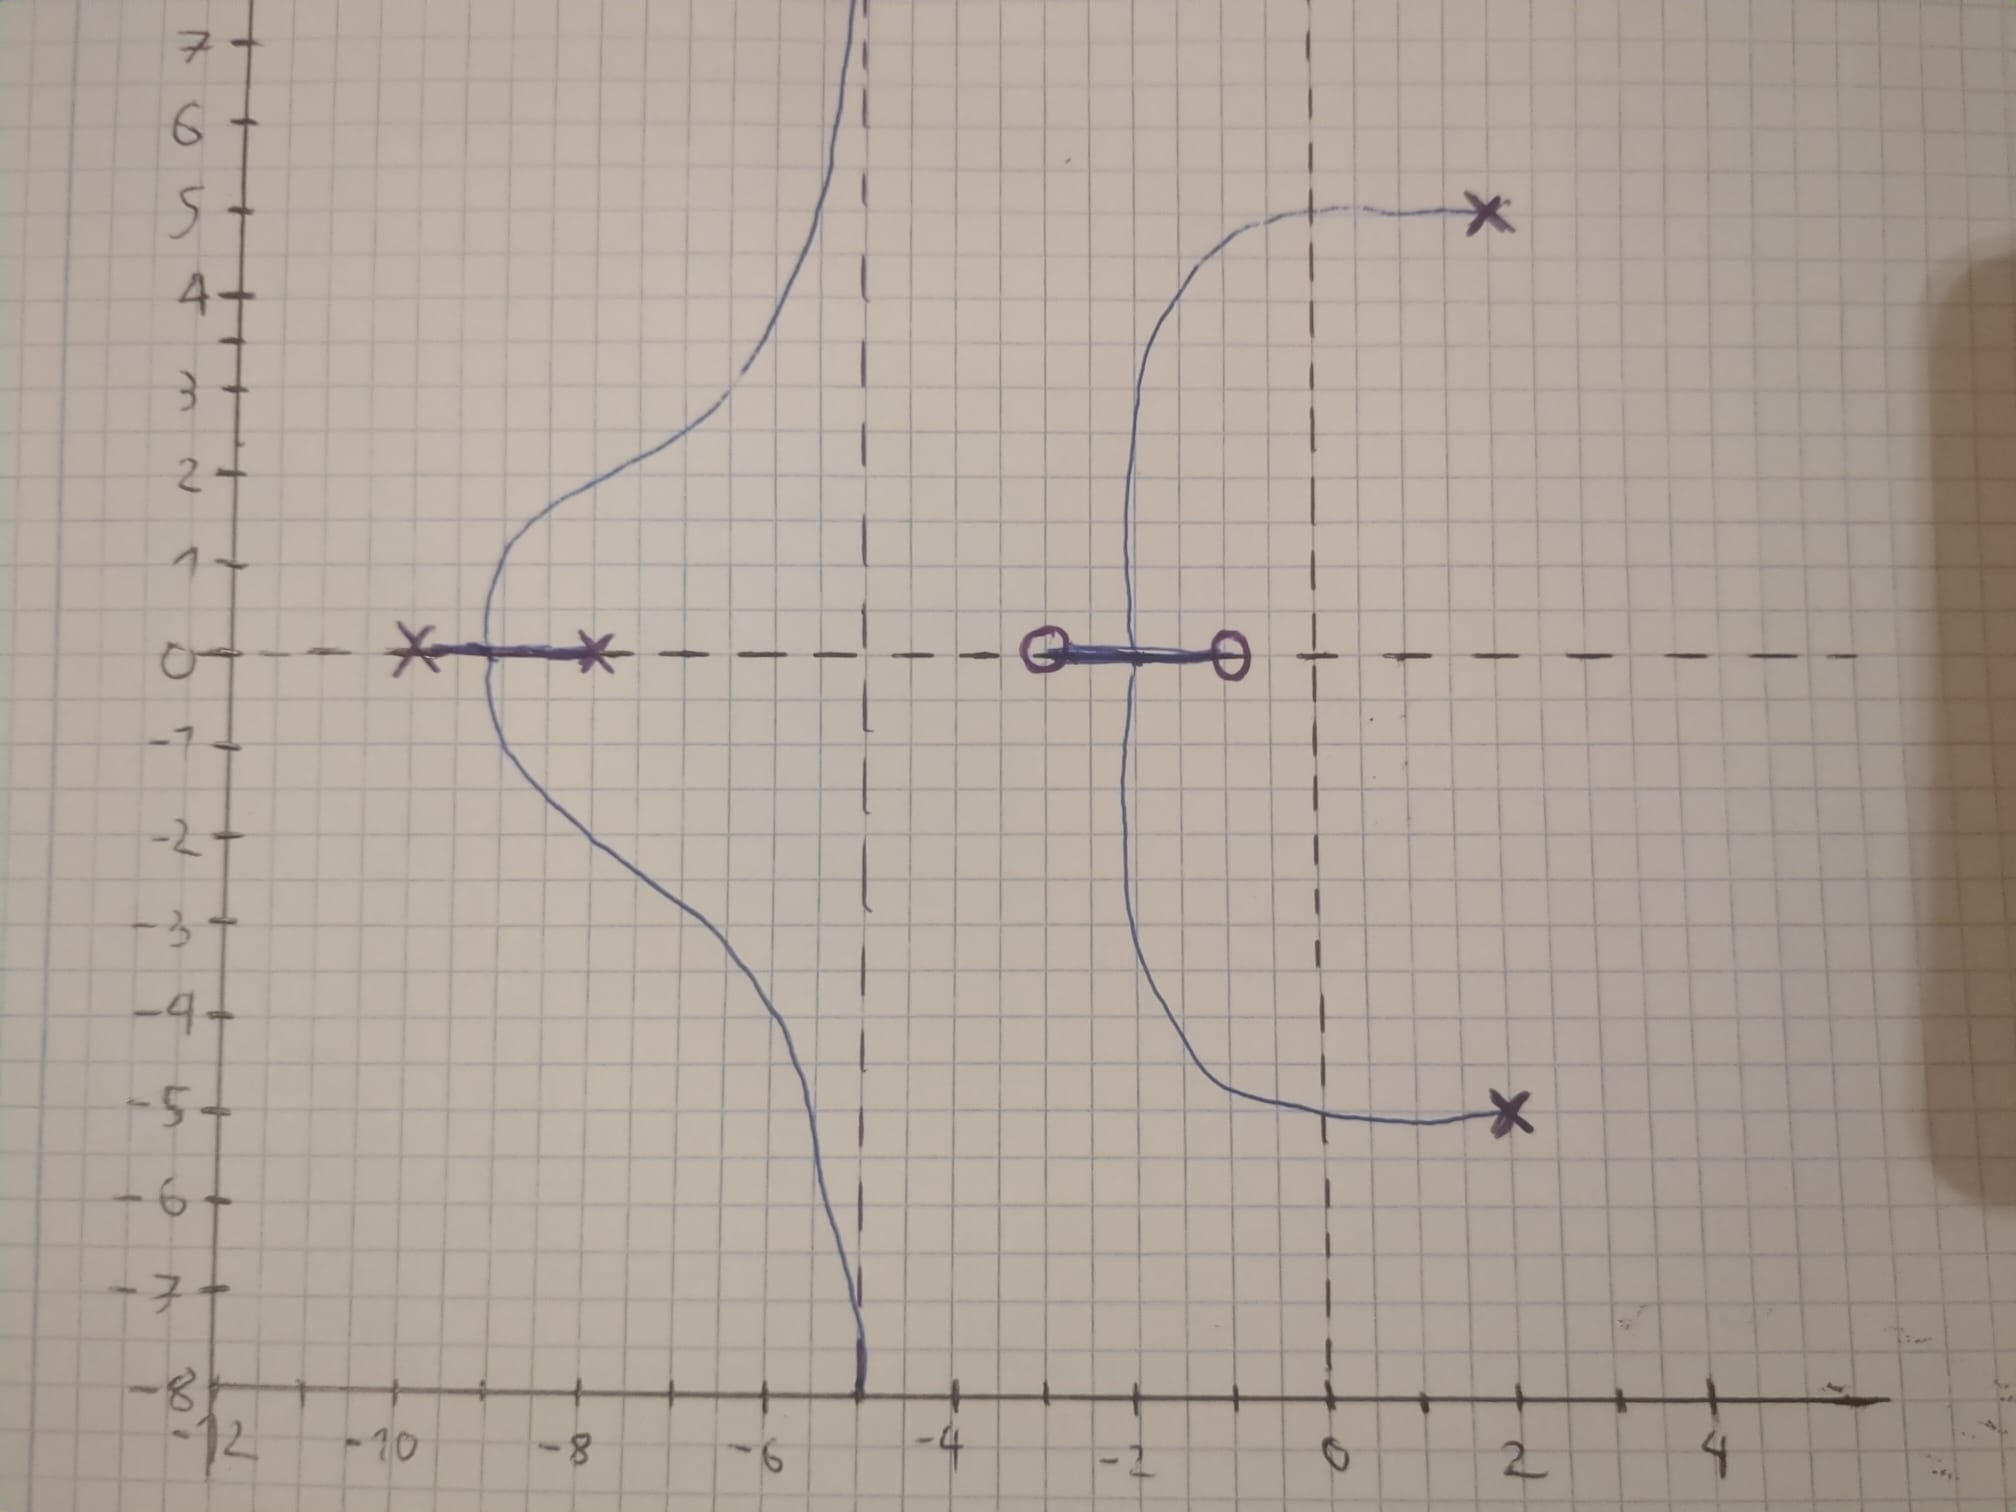

**b) Para el caso del sistema de la figura anterior, compare el resultado obtenido en base al procedimiento manual con el lugar de las raíces calculado directamente con Matlab. ¿Existen diferencias?, ¿A qué podrían ser debidas?**

Con Matlab calculamos el LDR con rlocus.

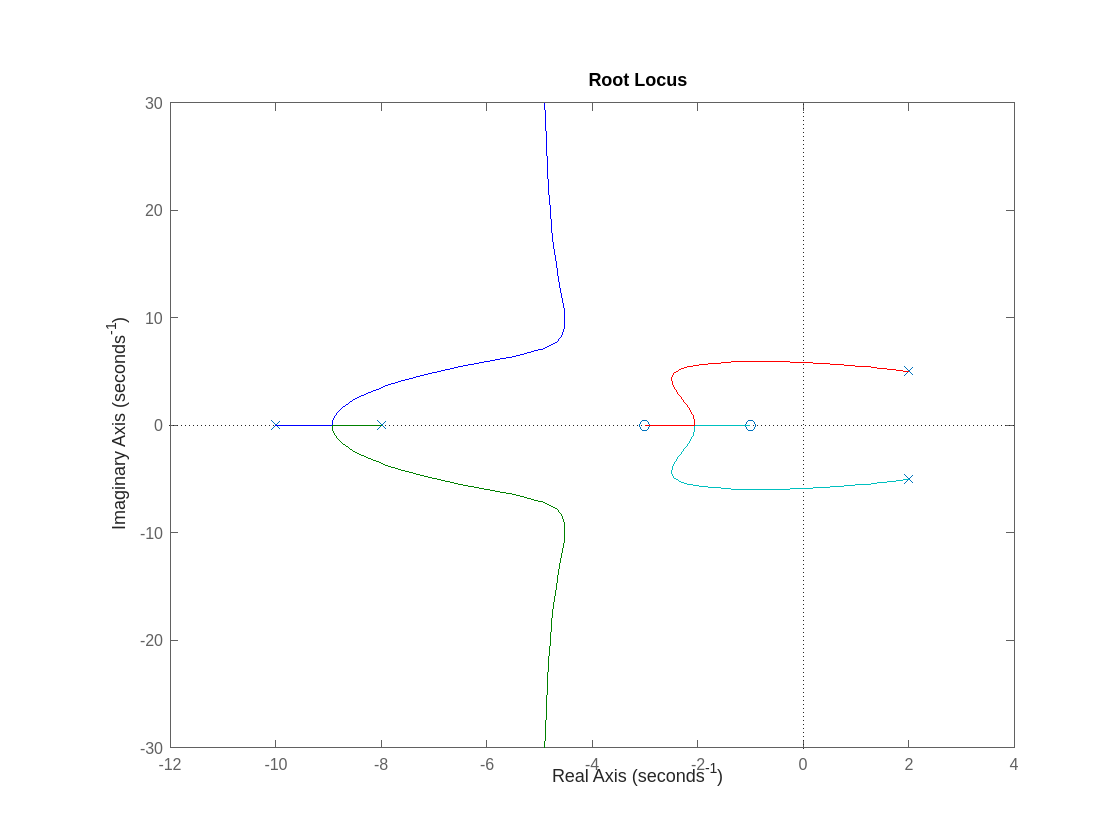

rlocus(G*H)

Como vemos los puntos calculados coinciden, pero las ramas son distintos, ya que los del dibujo son solo una aproximación, que podríamos ajustar buscando mas datos. 